SNR = 0;

# DeepMIMO dataset at SNR=0dB

load(['DeepMIMO_Data\Static_BS16\freq_symb_1ant_612sub_ver4\Gan_', num2str(SNR),'_dBOutdoor1_3p4_1ant_612subcs_Row_3500_3516.mat']);
H_data_source = H_data;

#### Distributions of H(k,m) in Real and Imag parts

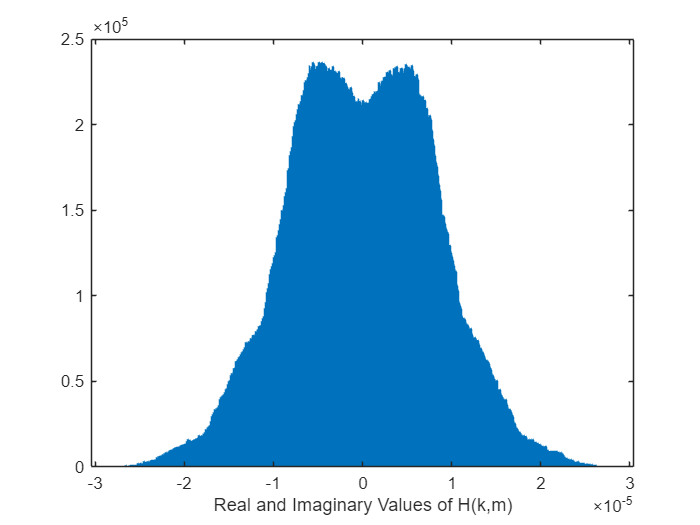

H_flat1 = H_data_source(:);
histogram(H_flat1, 'FaceColor',[0 0.4470 0.7410], 'EdgeColor',[0 0.4470 0.7410]);
xlabel('Real and Imaginary Values of H(k,m)');

% ylabel('Frequency');
% title('Distribution of Elements');

#### Distributions of H(k,m) in Real part 

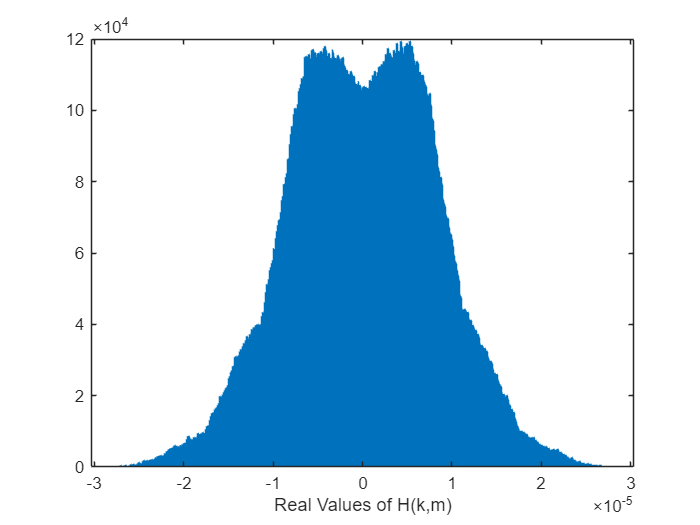

H_real1 = H_data_source(:,:,1,:);
H_real_flat1 = H_real1(:);
histogram(H_real_flat1, 'FaceColor',[0 0.4470 0.7410], 'EdgeColor',[0 0.4470 0.7410]);
xlabel('Real Values of H(k,m)');

% ylabel('Frequency');
% title('Distribution of Elements');

#### Distributions of H(k,m) in Imag part

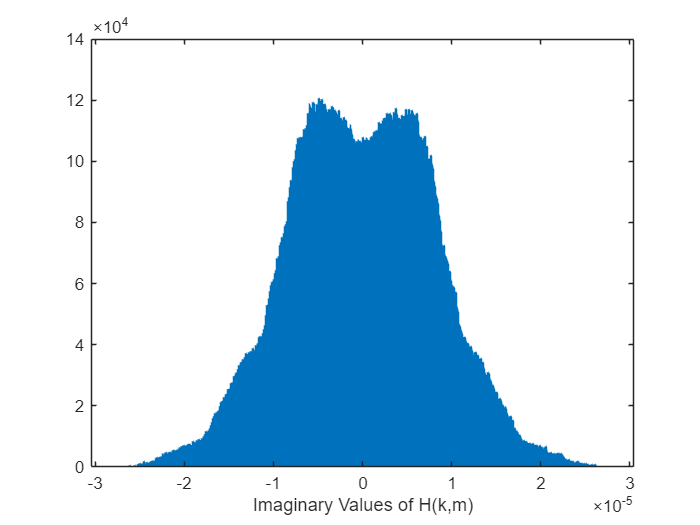

H_imag1 = H_data_source(:,:,2,:);
histogram(H_imag1(:), 'FaceColor',[0 0.4470 0.7410], 'EdgeColor',[0 0.4470 0.7410]);
xlabel('Imaginary Values of H(k,m)');

% ylabel('Frequency');
% title('Distribution of Elements');

#### Distribution of abs(H(k,m))

real_part1 = squeeze(H_data_source(:, :, 1, :));
imag_part1 = squeeze(H_data_source(:, :, 2, :));
H_complex1 = complex(real_part1, imag_part1);
H_abs1 = abs(H_complex1);

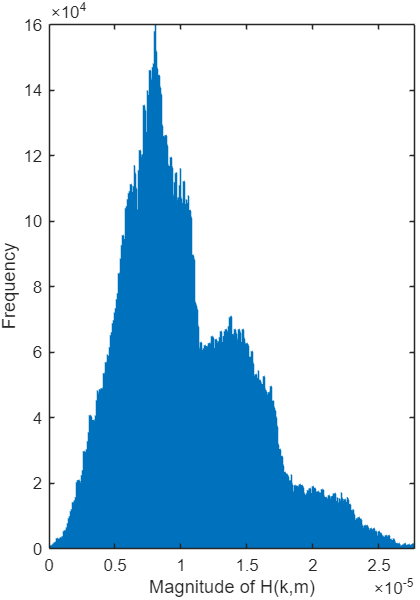

figure('Units', 'Inches', 'Position', [1, 1, 3.5, 5])
histogram(H_abs1(:), 'FaceColor',[0 0.4470 0.7410], 'EdgeColor',[0 0.4470 0.7410]);
xlabel('Magnitude of H(k,m)');
ylabel('Frequency');
axis tight;
ax = gca; % Get current axes
ti = ax.TightInset; % Get the tight inset values
ax.Position = [ti(1)+0.007, ti(2)+0.007, 1 - ti(1) - ti(3)-0.02, 1 - ti(2) - ti(4)-0.01]; % Adjust the axes position

set(gcf, 'PaperPositionMode', 'auto'); % For saving
print('DeepMIMO', '-dpng', '-r300'); % Save as PNG

% title('Magnitude of H(k,m)');

# DeepMIMO dataset at SNR=0dB

load(['..\CDL Customization\Data\ver39_\', num2str(SNR),'db\1_mapBaseData.mat']);
H_data_target = H_data;

#### Distributions of H(k,m) in Real and Imag parts

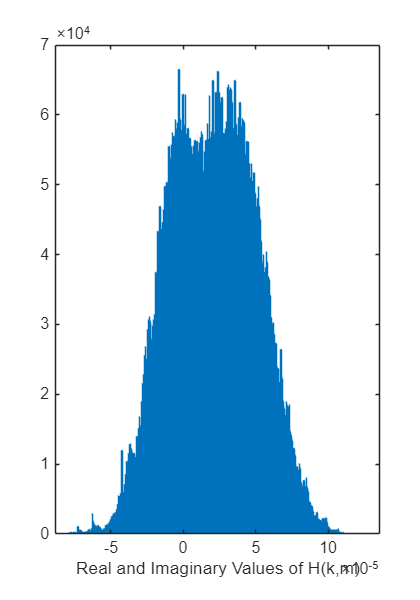

H_flat = H_data_target(:);
histogram(H_flat, 'FaceColor',[0 0.4470 0.7410], 'EdgeColor',[0 0.4470 0.7410]);
xlabel('Real and Imaginary Values of H(k,m)');

% ylabel('Frequency');
% title('Distribution of Elements');

#### Distributions of H(k,m) in Real part 

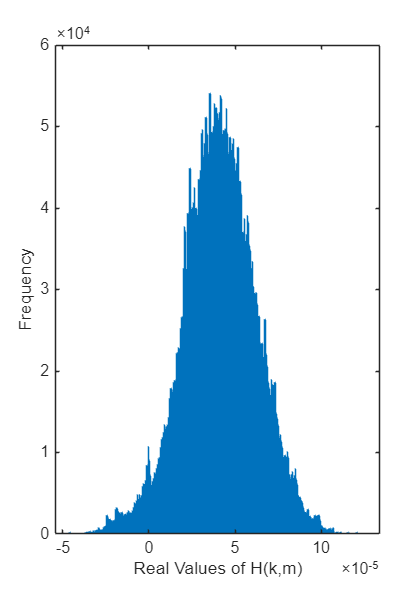

H_real = H_data_target(:,:,1,:);
H_real_flat = H_real(:);
histogram(H_real_flat, 'FaceColor',[0 0.4470 0.7410], 'EdgeColor',[0 0.4470 0.7410]);
xlabel('Real Values of H(k,m)');
ylabel('Frequency');

% title('Distribution of Elements');

#### Distributions of H(k,m) in Imag part

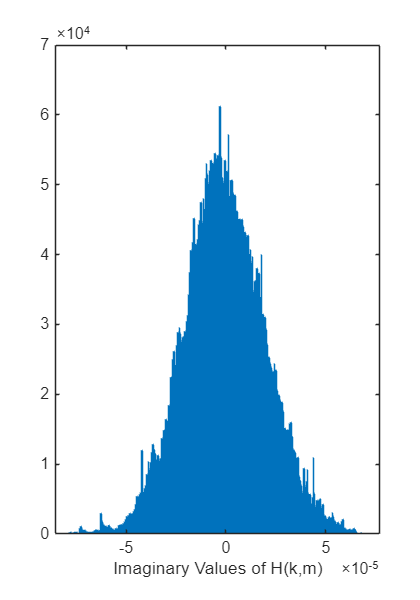

H_imag = H_data_target(:,:,2,:);
histogram(H_imag(:), 'FaceColor',[0 0.4470 0.7410], 'EdgeColor',[0 0.4470 0.7410]);
xlabel('Imaginary Values of H(k,m)');

% ylabel('Frequency');
% title('Distribution of Elements');

#### Distribution of abs(H(k,m))

real_part = squeeze(H_data_target(:, :, 1, :));
imag_part = squeeze(H_data_target(:, :, 2, :));
H_complex = complex(real_part, imag_part);
H_abs = abs(H_complex);

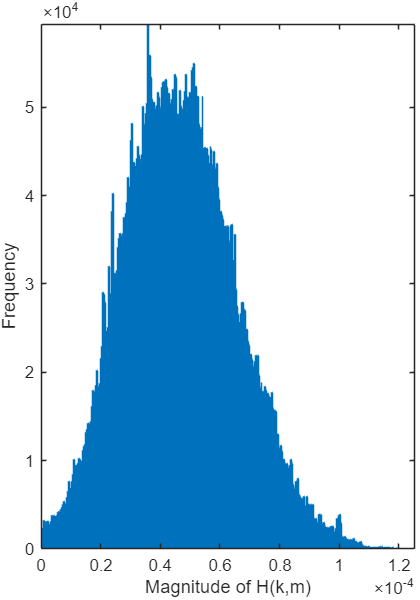

figure('Units', 'Inches', 'Position', [1, 1, 3.5, 5]);
histogram(H_abs(:), 'FaceColor',[0 0.4470 0.7410], 'EdgeColor',[0 0.4470 0.7410]);
xlabel('Magnitude of H(k,m)');
ylabel('Frequency');
axis tight;
ax = gca; % Get current axes
ti = ax.TightInset; % Get the tight inset values
ax.Position = [ti(1)+0.007, ti(2)+0.007, 1 - ti(1) - ti(3)-0.02, 1 - ti(2) - ti(4)-0.01]; % Adjust the axes position
set(gcf, 'PaperPositionMode', 'auto'); % For saving
print('mapBase', '-dpng', '-r300'); % Save as PNG

% title('Magnitude of H(k,m)');

# Calculate Wasserstein distance

H_source = complex(H_data_source(:,:,1,:), H_data_source(:,:,2,:));
H_target = complex(H_data_target(:,:,1,:), H_data_target(:,:,2,:));

n_source = size(H_data_source,4);
n_target = size(H_data_target,4);

% Reshape to 2D matrices
H_source_reshaped = reshape(H_source, [], n_source); % Shape: (14*612, 3077)
H_target_reshaped = reshape(H_target, [], n_target); % Shape: (14*612, 1000)

% Parameters for Sinkhorn approximation
epsilon = 1e-9;  % Small value for numerical stability
lambda = 1;      % Entropy regularization term
max_iter = 500;  % Maximum iterations for Sinkhorn

% Call the function to compute the Sinkhorn Wasserstein distance
sinkhorn_dist = sinkhorn_wasserstein(H_source, H_target, epsilon, lambda, max_iter);

% Initialize the Wasserstein-1 distance
% W_distance = zeros(n_source, n_target);

% Compute the pairwise Wasserstein-1 distance with Frobenius norm
% for i = 1:n_source
%     for j = 1:n_target
%         % Compute the Frobenius norm between the two matrices
%         W_distance(i, j) = norm(H_source(:,:,i) - H_target(:,:,j), 'fro');
%     end
% end
% 
% % You can compute the total Wasserstein distance if needed
% total_W_distance = sum(W_distance(:)); % Sum all pairwise distances
% 
% % Display the result
% disp('Pairwise Wasserstein-1 distances with Frobenius norm:');
% disp(W_distance);
% disp('Total Wasserstein-1 distance:');
% disp(total_W_distance);

%%% Approach 1: can not calculate when C has too large shape

% % Step 1: Compute the pairwise Frobenius norm between source and target samples
% C = zeros(n_source, n_target); % Cost matrix
% for i = 1:n_source
%     for j = 1:n_target
%         % Frobenius norm between source matrix i and target matrix j
%         C(i, j) = norm(H_source(:,:,i) - H_target(:,:,j), 'fro');
%     end
% end

% % Step 2: Define the supply and demand for the source and target
% % Each source sample is weighted equally, and so is each target sample
% p = ones(n_source, 1) / n_source; % Source distribution (supply)
% q = ones(n_target, 1) / n_target; % Target distribution (demand)
% 
% % Step 3: Solve the optimal transport problem using linear programming
% % Linear programming to minimize the transport cost (Wasserstein distance)
% 
% % We need to solve min f' * x subject to Aeq * x = beq and x >= 0
% f = C(:); % The cost matrix flattened into a vector
% 
% % Constraints for the linear programming problem
% Aeq = [kron(eye(n_source), ones(1, n_target)); kron(ones(1, n_source), eye(n_target))];
% beq = [p; q];
% 
% % Lower bounds (non-negative constraints)
% lb = zeros(n_source * n_target, 1);
% 
% % Use linprog to solve the linear program
% options = optimoptions('linprog', 'Display', 'none');
% [gamma, total_cost] = linprog(f, [], [], Aeq, beq, lb, [], options);
% 
% % Step 4: Compute the Wasserstein distance
% Wasserstein_distance = total_cost;
% 
% % Display the result
% disp('Wasserstein-1 distance with Frobenius norm:');
% disp(Wasserstein_distance);

%%%%% Aproach 2: Sinkhorn Approximation
function [sinkhorn_dist] = sinkhorn_wasserstein(H_source, H_target, epsilon, lambda, max_iter)
    % H_source: (14, 612, 3077)
    % H_target: (14, 612, 1000)
    % epsilon: Regularization term
    % lambda: Entropy regularization strength
    % max_iter: Number of Sinkhorn iterations
    
    % Reshape the source and target data
    H_source_reshaped = reshape(H_source, [], 3077); % (14*612, 3077)
    H_target_reshaped = reshape(H_target, [], 1000); % (14*612, 1000)

    % Number of samples in source and target
    n_source = 3077;
    n_target = 1000;
    
    % Step 1: Compute the cost matrix (Frobenius norm between source and target)
    C = zeros(n_source, n_target); % Cost matrix
    for i = 1:n_source
        for j = 1:n_target
            % Compute the Frobenius norm between source matrix and target matrix
            C(i, j) = norm(H_source(:,:,i) - H_target(:,:,j), 'fro');
        end
    end

    % Normalize cost matrix to avoid numerical instabilities
    C = C / max(C(:));
    
    % Step 2: Initialize variables for Sinkhorn iteration
    % Uniform source and target distributions (each matrix is equally weighted)
    p = ones(n_source, 1) / n_source;  % Source distribution
    q = ones(n_target, 1) / n_target;  % Target distribution
    
    % Initialize the scaling vectors (for the Sinkhorn-Knopp algorithm)
    u = ones(n_source, 1);  % Scaling for source
    v = ones(n_target, 1);  % Scaling for target

    % Step 3: Iterate Sinkhorn algorithm
    K = exp(-C / lambda);  % Gibbs kernel from the cost matrix
    for iter = 1:max_iter
        u = p ./ (K * v);  % Update scaling vector u
        v = q ./ (K' * u); % Update scaling vector v
    end

    % Step 4: Compute Sinkhorn distance
    % Transport plan pi = diag(u) * K * diag(v)
    transport_plan = diag(u) * K * diag(v);
    sinkhorn_dist = sum(sum(transport_plan .* C));  % Compute cost with transport plan

    % Display results
    disp('Sinkhorn Wasserstein-1 distance with Frobenius norm:');
    disp(sinkhorn_dist);
end
